# Быстрое преобразование Фурье в MATLAB

Чтение аудиофайла - запись колебания струны гитары (220 Гц).

[x,fs] = audioread('A220.mp3');
sound(x,fs);
x = x(1:2^15);

Быстрое проеобразование Фурье и попытка физуализировать спектр:

X = fft(x);
plot(X);

Построение амплитудного спектра сигнала:

area(abs(X));

Функция ***fftshift*** преобразует спектр (выход функции ***fft***) и сдвигает отсчёты симметрично относительно нулевой частоты:

Xshift = fftshift(X);
F = linspace(-fs/2,fs/2,length(X));
area(F,abs(Xshift));
xlim([-2e3 2e3]);
grid on; 
title('Амплитудный спектр сигнала');
xlabel('Частота (Гц)');
ylabel('Модуль БПФ');

Спектр в области положительных частот:

Xpositive = X([1:length(X)/2]);
Fpositive = linspace(0,fs/2,length(Xpositive));
area(Fpositive,abs(Xpositive));
xlim([0 1500]);
grid on;
hold on;
title('Амплитудный спектр сигнала');
xlabel('Частота (Гц)');
ylabel('Модуль БПФ');

Нахождение максимумов действительной части спектра:

[~,locs] = findpeaks(abs(Xpositive),'MinPeakHeight',100,...
                                    'MinPeakDistance',100);
Fpeaks = Fpositive(locs);                              
plot(Fpeaks,abs(Xpositive(locs)),'rv','MarkerFaceColor','r');
cellpeaks = cellstr(num2str(round(Fpeaks',-1)));
text(Fpeaks,abs(Xpositive(locs)),cellpeaks,'FontSize',16);
hold off;

Основные частоты нот:

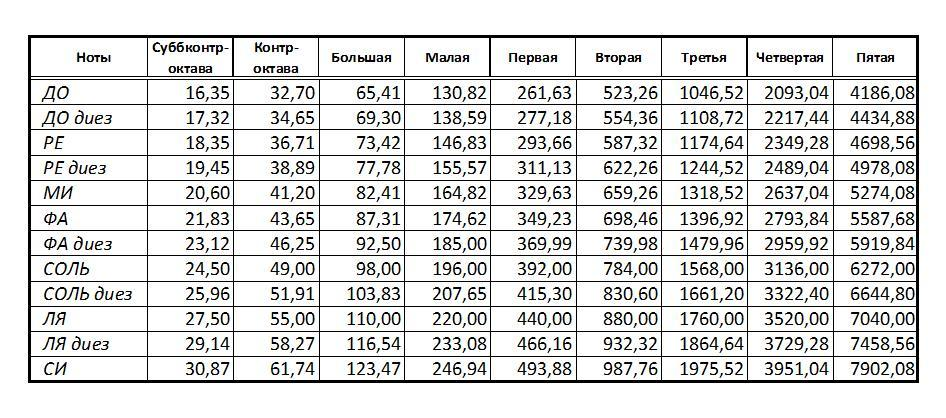

Обратное быстрое преобразование Фурье (ОБПФ) - функция ***ifft***:

y = ifft(X);
sound(y,fs);